# Getting Started with `parfor` 

In this exercise, we will convert a simple `for`-loop into a `parfor`-loop and understand the basic differences between the two types of loops.

doc parfor

## How much time will the following `for`-loop take?

This is an example of a basic `for`-loop; in each iteration, `pause(1)` stops MATLAB execution for one second and then displays the index `idx` of the iteration. Since there are 10 iterations, the `for`-loop takes about 10 seconds (the added `tic` and `toc` measure the time elapsed) and the indices are displayed sequentially, from 1 to 10.

tic
for idx = 1:10
    pause(1)
    disp(idx)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



toc
toc

Elapsed time is 10.287360 seconds.


## How much time will the corresponding `parfor`-loop take?

Rewrite the `for`-loop from the previous example to run as a `parfor`-loop. You should notice the order of the displayed indices changes, because the loop iterations are executed in parallel in a non-deterministic order. This does not impact the loop iterations, since the individual iterations are independent. Is the code running faster?

tic
parfor idx = 1:10 % TODO rewrite this line
    pause(1)
    disp(idx)
end

     3

     5

     6

     7

     1

     2

     4

     8

     9

    10



Elapsed time is 1.832587 seconds.


Elapsed time is 1.834904 seconds.


toc

Did your code run slower than the serial `for`-loop? If no parallel pool was open when you ran the code, `parfor` started a new pool, which can add significant overhead to the elapsed time. 

You can set your parallel preferences not to create a parallel pool automatically when parallel keywords like `parfor` are executed. (*Note that the Preferences options pane is not available in MATLAB Online.*)

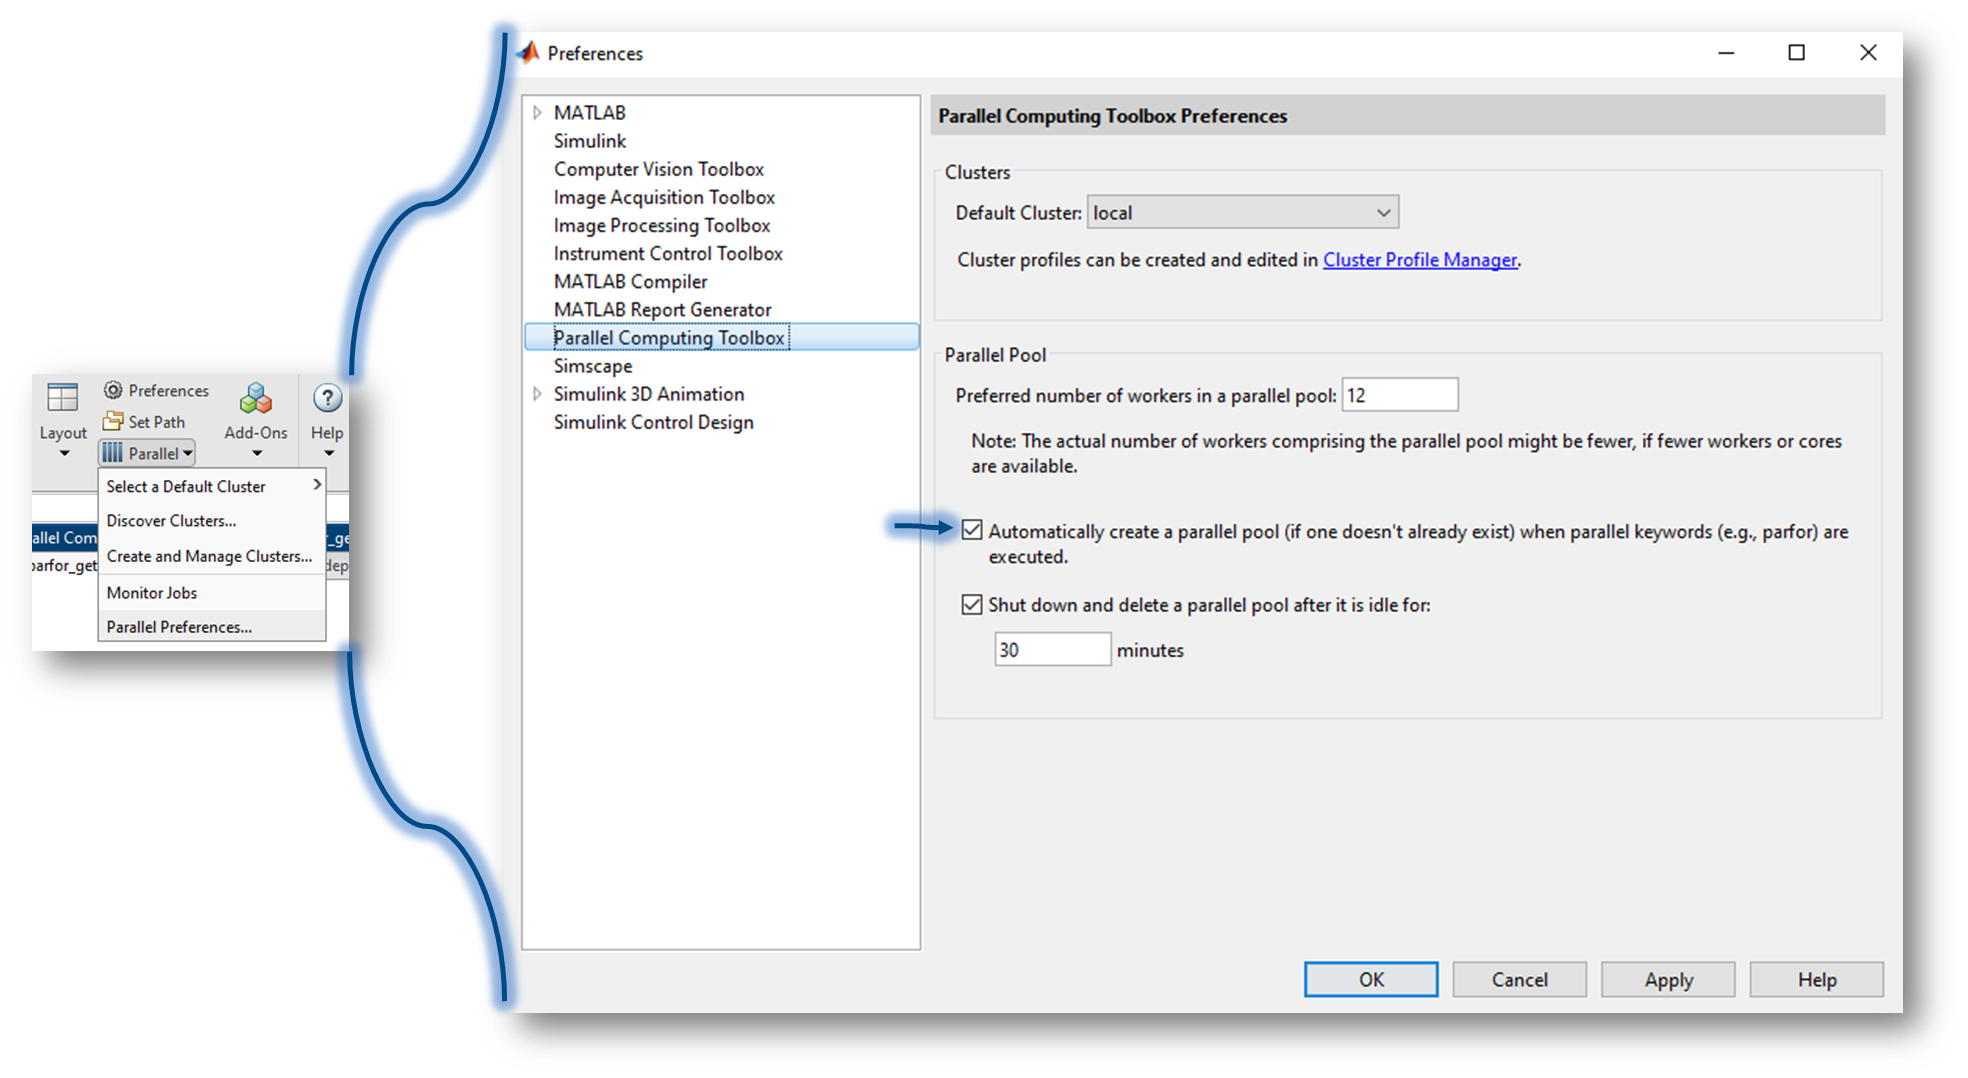

You can also explicitly create a parallel pool to control when you incur the overhead time of setting the parallel pool up, either from the pool status indicator or programmatically using `parpool`.

The pool status indicator in the lower-left corner of the desktop shows the client section connection to the pool and the pool status. (*Note the parallel status indicator is not visible by default in MATLAB Online. You must start a parallel pool first by using *[`parpool`](https://www.mathworks.com/help/parallel-computing/parpool.html)* or any of the functions that automatically start a parallel pool*.)

With a pool running: 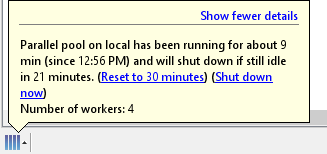

With no pool running: 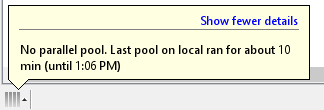

With default preferences, MATLAB starts a pool on the local machine with one worker per physical CPU core, up to the preferred number of workers. You can use `gcp` to get the current parallel pool (or start a new pool if no parallel pool exists and automatic pool starts are enabled; alternatively, the '`nocreate`' option causes `gcp` not to create a pool, regardless of your settings).

p = gcp;

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 118
              Cluster: 

disp(p)

When creating a parallel pool, you can also use `parpool(poolsize)` specify the pool size to override the number of workers specified in the preferences or profile, and start a pool of exactly that number of workers, even if it has to wait for them to be available. 

Note that you can't run multiple parallel pools at the same time. Use `delete(p)` to shut down the parallel pool associated with p, or `delete(gcp('nocreate'))` to delete a pool if it exists, but without creating one first if a parallel pool doesn't already exist.

## How much time will the corresponding `parfor`-loop take with an open parallel pool

tic
parfor idx = 1:10 % TODO rewrite this line
    pause(1)
    disp(idx)
end

Starting parallel pool (parpool) using the 'local' profile ...


toc

Elapsed time is 1.441544 seconds.


Elapsed time is 1.442883 seconds.
